# Visualizations of Northern Hemisphere Sea Ice Concentration 

Kelly Luetkemeyer (The MathWorks Inc., Natick (MA), USA) & Steve Schäfer (The MathWorks GmbH, Aachen, Germany) 

Copyright 2020 The MathWorks, Inc.

This example illustrates how to obtain and use data from the [Copernicus Climate Data Store](https://cds.climate.copernicus.eu/#!/home) to map sea ice concentration in the northern hemisphere from 1978 to 2014. The dataset was produced at the EUMETSAT Ocean and Sea Ice Satellite Application Facility (OSI SAF) as Global Sea Ice Concentration Climate Data Records (1978-2015) [1]. The dataset is available for download from the [Copernicus Climate Data Store](https://cds.climate.copernicus.eu/cdsapp#!/dataset/satellite-sea-ice?tab=overview) as well as the [EUMETSAT OSI SAF webportal](http://osisaf.met.no/p/ice/index.html#conc-reproc), in Network Common Data Form (NetCDF) file format.

This example visualizes the annual changes in sea ice concentration. December is used as a yearly reference month and utilized for the covered years of the simulations. For this example, the data set is stored in a local folder named `data`. 

MATLAB supports high-level functions for reading and writing NetCDF files and provides the NetCDF Library Package for low-level functionality. A detailed function overview is given in the [MATLAB documentation](https://www.mathworks.com/help/matlab/network-common-data-form.html). This example uses these functions and other built-in features to preprocess the data, and to build multiple visualizations  in 2D and 3D. The required steps are explained and illustrated below.

## Steps to Obtain Data from Copernicus Climate Data Store

Illustrated below are the steps to obtain data from the [Copernicus Climate Data Store](https://cds.climate.copernicus.eu/#!/home).

### Step 1: Create Account

You need to register for a free account [here](https://cds.climate.copernicus.eu/user/register).

### Step 2: Search for your Dataset

Search for your dataset [here](https://cds.climate.copernicus.eu/cdsapp#!/search?type=dataset).

### Step 3: Select your Dataset

For example, the selection for this example is illustrated below:

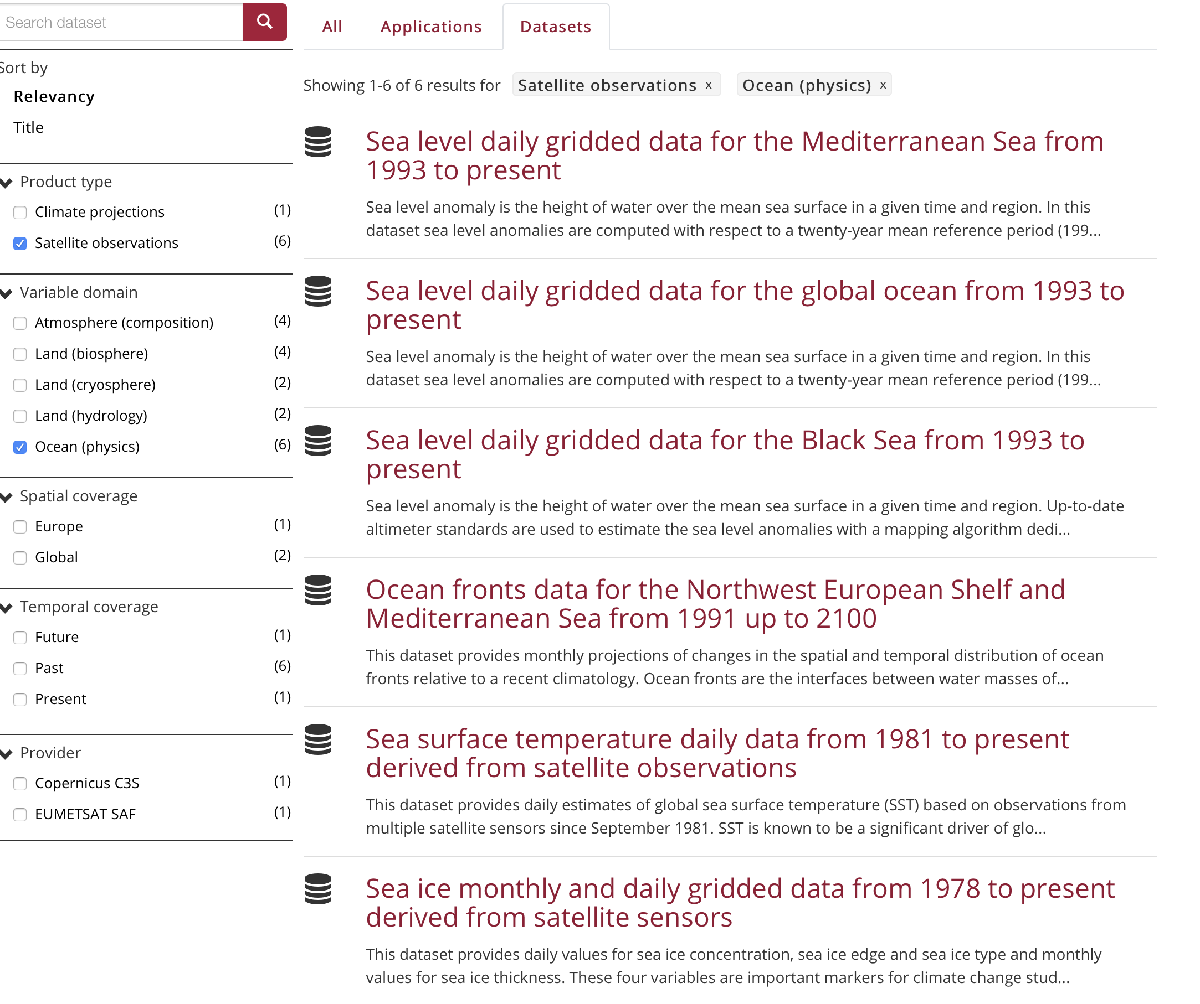

### Step 4: Select Dataset and Download Data

The selection for this demo is highlighted below. Click on the "Download data" link to refine your selection (step 5).

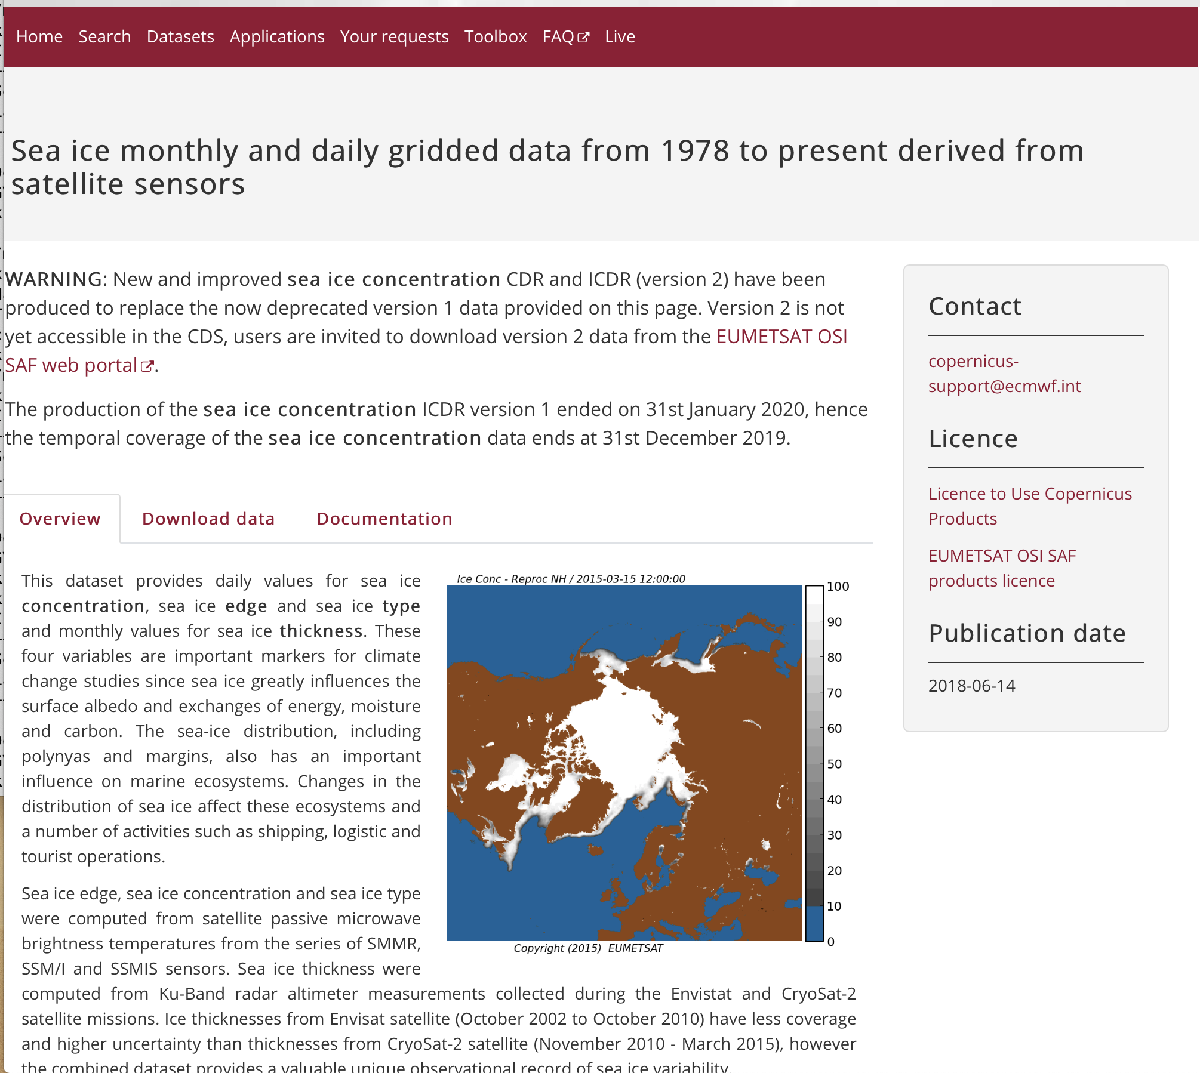

### Step 5: Refine your selection

Click on "[Download data](https://cds.climate.copernicus.eu/cdsapp#!/dataset/satellite-sea-ice?tab=form)" A form will open. This example uses the following selected data in the form.

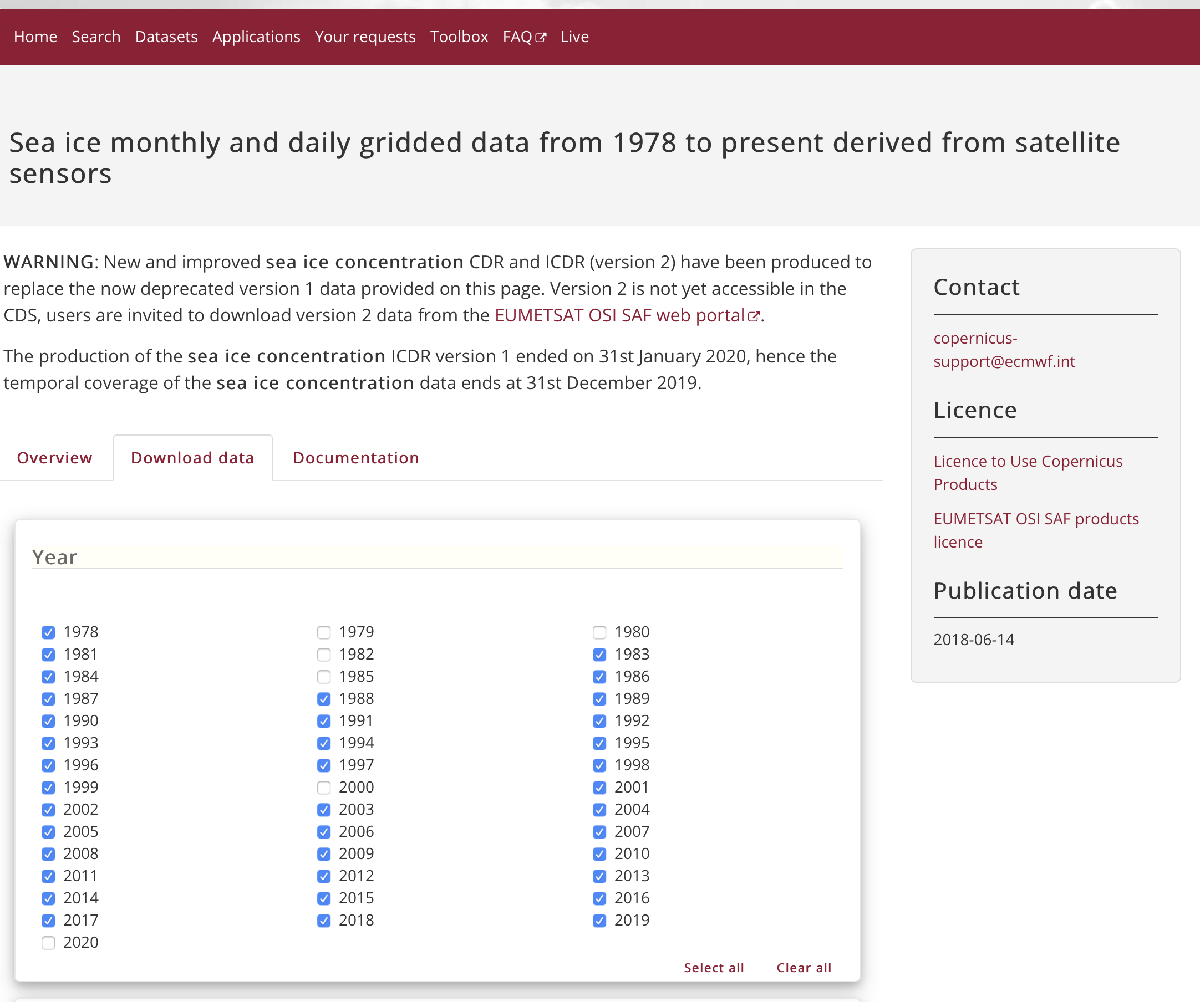

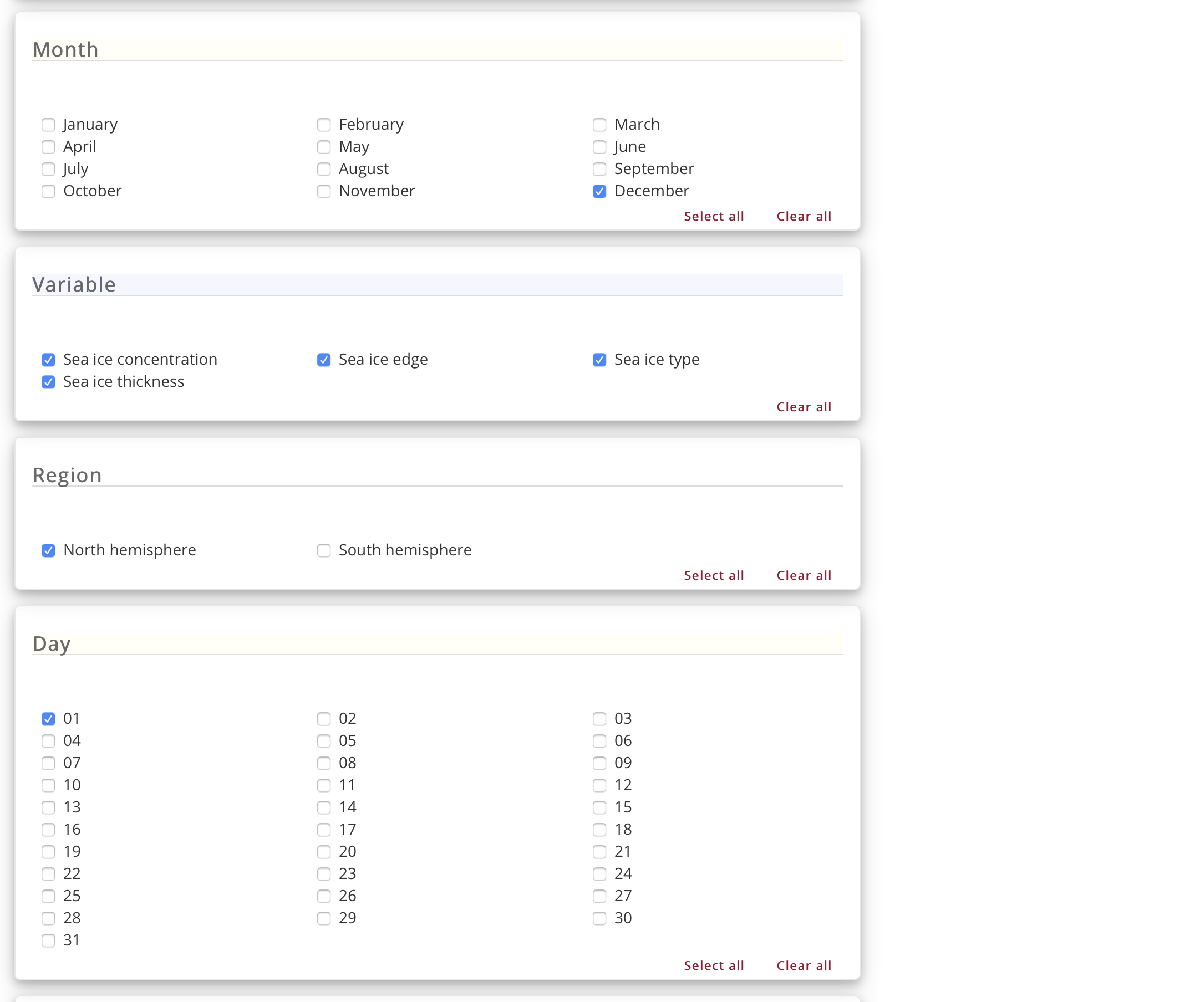

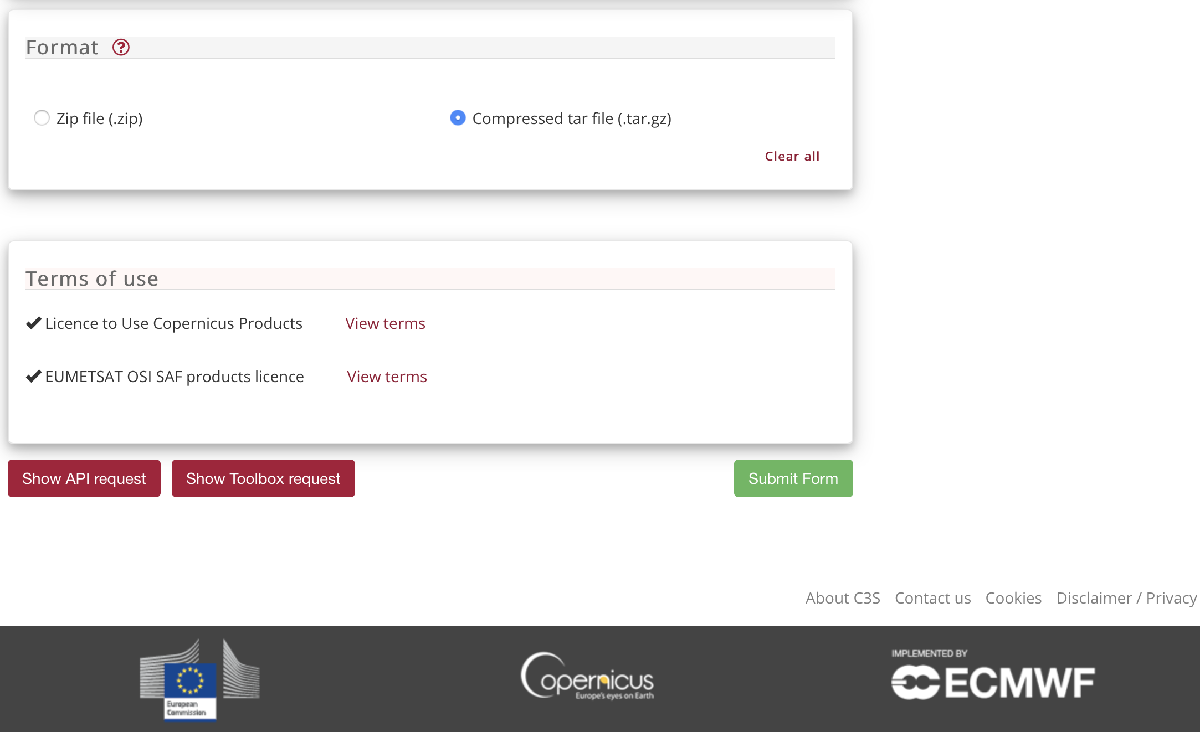

### Step 6: Submit Form

Click on Submit Form and wait for the data. Once the data is obtained, click on the "Download" form.

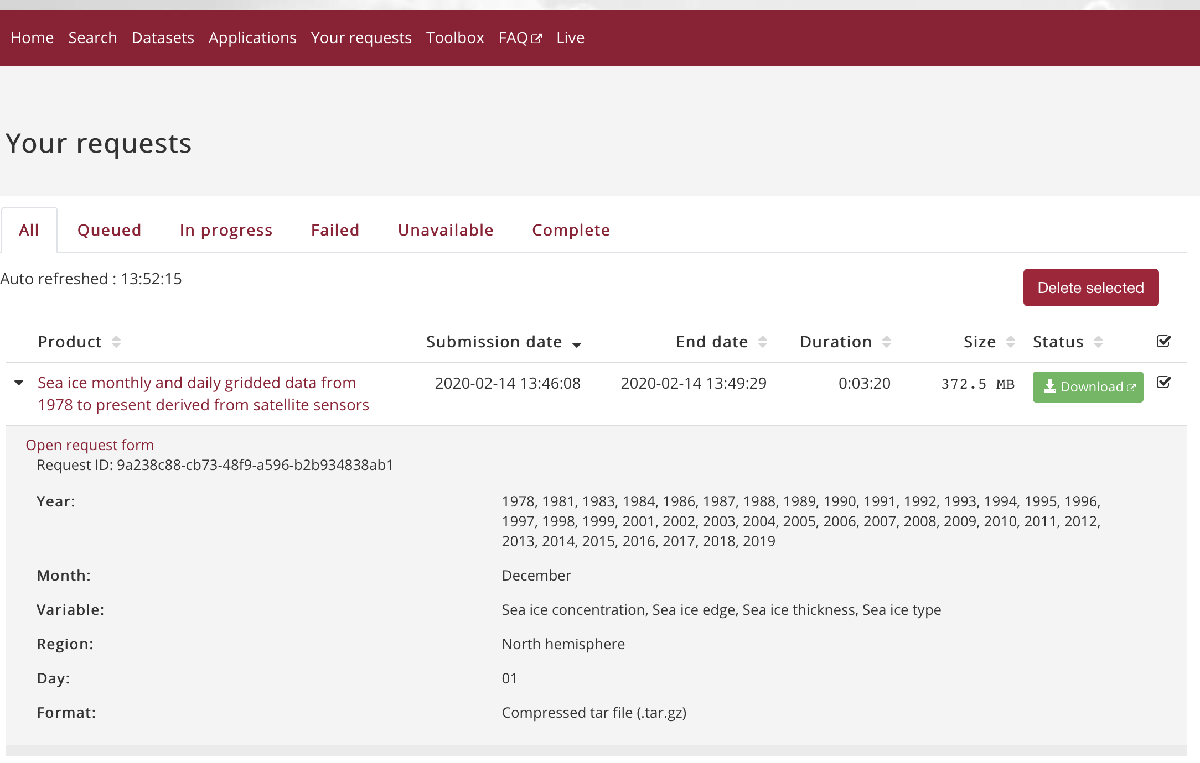

### Step 7: Extract Data Files

The data files are either zipped or in a compressed tar file. Use your operating system to extract the data files. The tar file is 818MB in size and contains 94 NetCDF files. This example expects the data files stored in a `data` folder. You need to manually create a `data` folder then copy the downloaded tar file or zip file to the `data` folder and extract the contents.

## Create Variable Containing Data Files with Ice Concentration

Find files for sea ice concentration in NetCDF4 data format.

if ~exist("data","dir")
    error("You need to create a data folder and copy the downloaded file to the data folder and extract contents.")
end

datafolder = fullfile(pwd,"data");
t = struct2table(dir(fullfile(datafolder,"*")));
files = string(t.name(contains(t.name,"conc") & contains(t.name,".nc4")));

## Examine Ice Concentration Data

Examine the contents of the file using the [ncdisp](https://www.mathworks.com/help/matlab/ref/ncdisp.html) function.

file = fullfile(datafolder,files(1));
ncdisp(file)

Source:
           /private/tmp/copernicus/data/ice_conc_nh_ease-125_reproc_197812011200.nc4
Format:
           netcdf4_classic
Global Attributes:
           title                  = 'OSI SAF Global Sea Ice Concentration Reprocessing'
           product_id             = 'OSI-409'
           product_name           = 'osi_saf_ice_conc_reproc'
           product_status         = 'offline'
           abstract               = 'The reprocessing of sea ice concentration  is  obtained  from
                                    passive microwave satellite data over the polar  regions.  It
                                    is based on atmospherically corretected signal and an optimal
                                    sea ice concentration algorithm. This  product  is  available
                                    for free from  the  EUMETSAT  Ocean  and  Sea  Ice  Satellite
                                    Application Facility (OSI SAF).'
           topiccategory          = 'Oceans Climato

cachefile = fullfile(datafolder,"ice_conc_cache.mat");
if exist(cachefile,"file")
    cache = load(cachefile);
    years = string(extractAfter(fieldnames(cache),"Year_"))
else
    
    years = extractAfter(files,"reproc_");
    years = extractBefore(years,"12011200.nc4")
end

years = 32×1 string array
    "1978"
    "1981"
    "1983"
    "1984"
    "1986"
    "1987"
    "1988"
    "1989"
    "1990"
    "1991"
    "1992"
    "1993"
    "1994"
    "1995"
    "1996"
    "1997"
    "1998"
    "1999"
    "2001"
    "2002"
    "2003"
    "2004"
    "2005"
    "2006"
    "2007"
    "2008"
    "2009"
    "2010"
    "2011"
    "2012"


## Read Ice Concentration Data and Copyright Attribute

Read variables from the file using the [ncread](https://www.mathworks.com/help/matlab/ref/ncread.html) function. Read copyright information, using the [ncreadatt](https://www.mathworks.com/help/matlab/ref/ncreadatt.html) function. Update copyright based on the [EUMETSAT OSI SAF products license](https://cds.climate.copernicus.eu/api/v2/terms/static/eumetsat-osi-saf.pdf).

ice_concentration = ncread(file,"ice_conc");
lat = ncread(file,"lat");
lon = ncread(file,"lon");

copyright = string(ncreadatt(file,"/","copyright_statement"));
year = extractBetween(copyright," "," ");
copyright = replaceBetween(copyright," "," ","(" + year + ")");
copyright = replace(copyright, "Copyright", "Copyright ©")

copyright = "Copyright © (2011) EUMETSAT"

## Visualize Sea Ice Concentration in 2D Map

Create a map with a Lambert Equal Area Azimuthal projection with the origin at the North Pole to visualize ice concentration for December 1978. Use a grid color of white.

data = load(fullfile(pwd,"data","ice_colormap"));
ice_colormap = data.ice_colormap;
land = shaperead("landareas","UseGeoCoords",true);

startYear = years(1);
attribution = copyright;
titlestr = ["Ice Concentration"; "December " + startYear; attribution];

gcolor = [1 1 1];
landcolor = [204 204 204]/255;
levels = 0:5:100;
latlim = double([min(lat(:)) max(lat(:))]);

figure("Colormap",ice_colormap)
title(titlestr)
ax = axesm("eqaazim", ...
    "Origin",[90 0 0],"MapLatLimit",latlim, ...
    "Grid","on","GColor",gcolor);
caxis(ax,[min(levels) max(levels)])

Set the axes limits to zoom into the map.

axis(ax,"off")
nlim = .82;
set(ax,"XLim",[-nlim,nlim],"YLim",[-nlim,nlim])

Display polygons of land areas and a texture map of ice concentrations.

geoshow(lat,lon,ice_concentration,"DisplayType","texturemap");
geoshow(land,"FaceColor",landcolor)

Add a color bar and label.

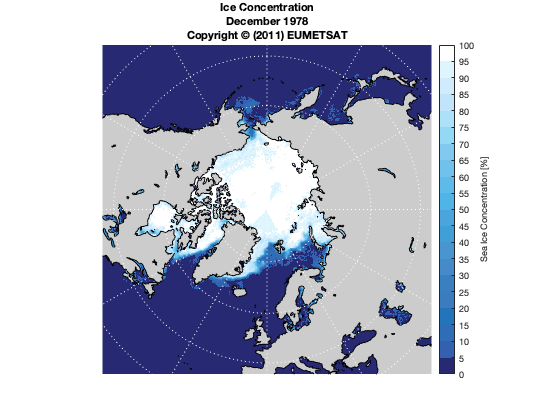

h = colorbar("Ticks",levels);
h.Label.String = "Sea Ice Concentration [%]";

## Animate Sea Ice Concentration Over Time in Live Editor

An animation is helpful to visualize change. Show changes in plotted data over time by animating the yearly changes in ice concentration using the Live Editor. The [drawnow](https://www.mathworks.com/help/matlab/ref/drawnow.html) function displays the changes after each iteration through the loop. 

makemap(latlim,ice_colormap);
iceTextureMap = geoshow(lat,lon,ice_concentration,"DisplayType","texturemap");
geoshow(land,"FaceColor",landcolor)

for k = length(years):-1:1
    year = years(k);
    [ice_concentration, newTitle] = readData(file,cachefile,startYear,year);
    set(iceTextureMap,"CData",ice_concentration)
    title(newTitle)
    drawnow
end

## Animate Sea Ice Concentration Using Animated GIF

To share the animation with others, write the frames to an animated GIF file. The animated GIF image is enclosed below.

hfig = makemap(latlim,ice_colormap,"Visible","off");
iceTextureMap = geoshow(lat,lon,ice_concentration,"DisplayType","texturemap");
geoshow(land,"FaceColor",landcolor)

filename = 'sea_ice_animation.gif';
if exist(filename,'file')
    delete(filename)
end
for k = 1:length(years)
    year = years(k);
    [ice_concentration, newTitle] = readData(file,cachefile,startYear,year);
    set(iceTextureMap,"CData",ice_concentration)
    title(newTitle)
    writeAnimatedGIF(hfig,filename)
end

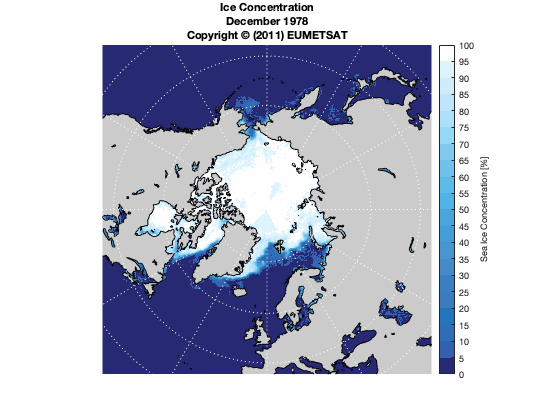

**Figure 1**: Animation of sea ice concentration from December 1978 to December 2014.

## Visualize Sea Ice Concentration in App

Run the `iceConcentrationApp` to easily visualize ice concentration for different years.

iceConcentrationApp

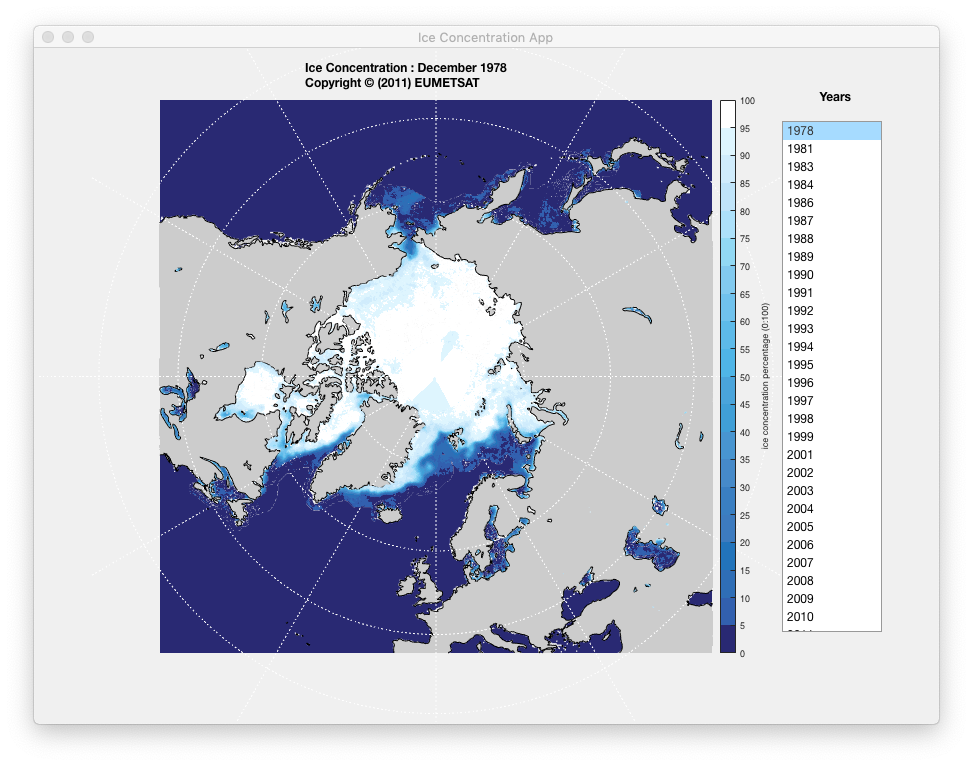

**Figure 2**: Screen shot of App showing the percentage of sea ice concentration from 0 to 100 percent for December 1978.

## Visualize Contours of Sea Ice Concentration in 2D Map

Create a contour map to visualize sea ice concentration. A contour map provides greater visual distinction between the different levels of ice concentrations.

Create a new figure and map axes for the contour map. 

makemap(latlim,ice_colormap);

Select year of interest using Live Controls. The Live Control is configured to rerun the section upon changes.

year = "1978";
[ice_concentration, newTitle, attribution] = readData(file,cachefile,startYear,year);
title(newTitle)

Use [`geoloc2grid`](matlab:doc('geoloc2grid')) to create a regular gridded data set from longitude and latitude information.

warning off map:geoloc2grid:possibleLongitudeWrap
cellSize = .5;
[Z,refvec] = geoloc2grid(double(lat),double(lon),ice_concentration,cellSize);

Display ice concentration, land data, and create contour lines.

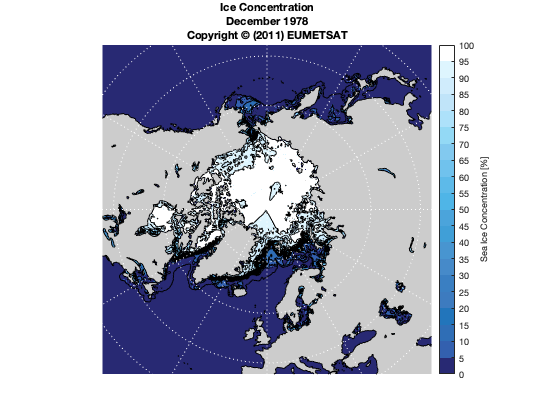

geoshow(lat,lon,ice_concentration,"DisplayType","texturemap")
geoshow(land,"FaceColor",landcolor)
iceContourMap = contourm(Z,refvec,"LevelList",levels,"Color","k");

## Visualize Contours of Sea Ice Concentration in 3D Globe

Visualize contours of sea ice on the geographic globe. Convert the contour matrix created with contourm to a geoshape vector. Display the contour lines onto a geographic globe and include a colorbar.

s = contourToGeoshape(iceContourMap);

uif = uifigure("Colormap",ice_colormap,"Visible","off");
uif.Name = "Ice Concentration : December " + year + " " + attribution;
ug = uigridlayout(uif,[1,2],"ColumnWidth",{'1x','.1x'});
up1 = uipanel(ug,"BackgroundColor",uif.Color,"BorderType","none");
up2 = uipanel(ug,"BackgroundColor",uif.Color,"BorderType","none");

gg = geoglobe(up1,"Terrain","none","Basemap","streets-dark","NextPlot","add","Visible","off");

ax = axes(up2,"Units","normalized","Position",[.05 0.02 .005 .95]);
axis(ax,"off")
caxis(ax,[0 100])
h = colorbar(ax);
h.Label.String = "Sea Ice Concentration [%]";
h.Ticks = levels;

n = 0;
for level = levels
    index = s.Level == level;
    n = min(n + 1, length(ice_colormap));
    color = ice_colormap(n,:);
    geoplot3(gg,s(index).Latitude,s(index).Longitude,[],"Color",color)
end

uif.Visible = "on";
gg.Visible = "on";

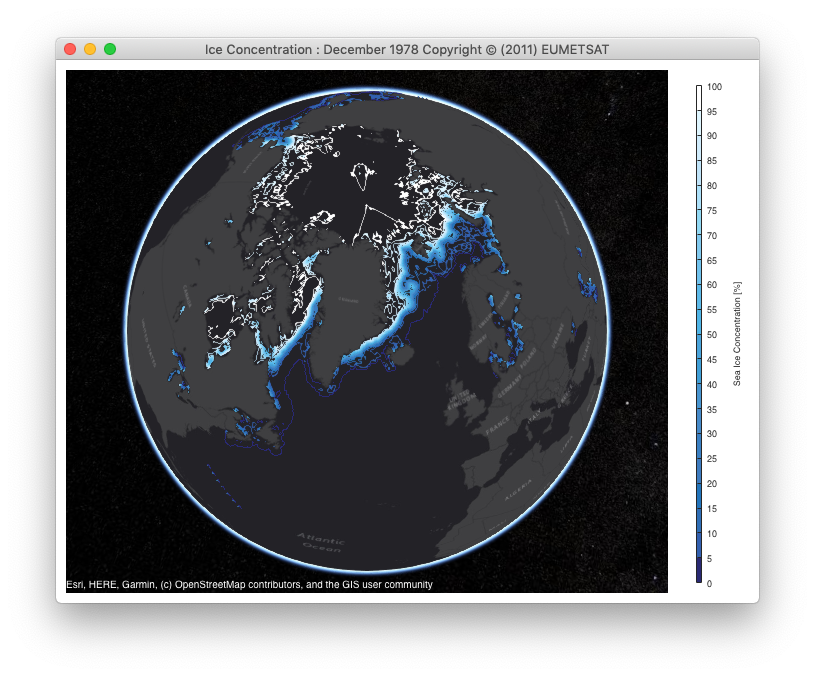

**Figure 3**: Screen shot of the geographic globe with contour lines showing the percentage of sea ice concentration from 0 to 100 percent for December 1978.

## References

[1] EUMETSAT Ocean and Sea Ice Satellite Application Facility. *Global sea ice concentration climate data records 1978-2015* (v1.2, 2015), [Online]. Norwegian and Danish Meteorological Institutes. doi: [http://dx.doi.org/10.15770/EUM_SAF_OSI_0001](http://dx.doi.org/10.15770/EUM_SAF_OSI_0001) and [http://dx.doi.org/10.15770/EUM_SAF_OSI_0005](http://dx.doi.org/10.15770/EUM_SAF_OSI_0005).

## Local Functions

### Create new map axes for display of ice concentration

function hfig = makemap(latlim,ice_colormap,varargin)
    gcolor = [1 1 1];
    levels = 0:5:100;
    
    hfig = figure("Colormap",ice_colormap,varargin{:});
    ax = axesm("eqaazim",...
        "Origin",[90 0 0],"MapLatLimit",latlim, ...
        "Grid","on","GColor",gcolor);
    
    caxis(ax,[min(levels),max(levels)])
    axis(ax,"off")
    nlim = .82;
    set(ax,"XLim",[-nlim,nlim],"YLim",[-nlim,nlim])
    
    h = colorbar;
    h.Ticks = levels;
    h.Label.String = "Sea Ice Concentration [%]";
end

### Read ice concentration and copyright attribute

function [ice_concentration, newTitle, attribution] = readData(file,cachefile,startYear,year)
yearfile = replace(file,startYear,year);
if exist(yearfile,"file")
    ice_concentration = ncread(yearfile,"ice_conc");
    copyright = ncreadatt(yearfile,"/","copyright_statement");
else
    yearstr = "Year_" + year;
    data = load(cachefile,yearstr);
    ice_concentration = data.(yearstr).IceConcentration;
    copyright = data.(yearstr).Copyright;
end
copyYear = extractBetween(copyright," "," ");
copyright = replaceBetween(copyright," "," ","(" + copyYear + ")");
copyright = replace(copyright, "Copyright", "Copyright ©");

attribution = copyright;
newTitle = ["Ice Concentration"; "December " + year; attribution];
end

### Convert  contour matrix created with contourm to geoshape vector

function s = contourToGeoshape(c)
    lon = c(1,:);
    lat = c(2,:);
    n = length(lat);
    k = 1;
    index = 1;
    S = struct("Lat",[],"Lon",[],"Level",[]);
    while k < n
        level = lon(k);
        numVertices = lat(k);
        S(index).Lat = lat(k+1:k+numVertices);
        S(index).Lon = lon(k+1:k+numVertices);
        S(index).Level = level;
        k = k + numVertices + 1;
        index = index + 1;
    end
    
    % Remove single vertex.
    s = geoshape(S);
    index = false(length(s),1);
    for k = 1:length(s)
        if isscalar(s(k).Latitude)
            index(k) = true;
        end
    end
    s(index) = [];
end


### Get frame and write as animated GIF

function writeAnimatedGIF(hfig, filename)
    data = getframe(hfig);
    RGB = data.cdata;
    [frame, cmap] = rgb2ind(RGB, 256, 'nodither');
    
    % Write frame to the GIF File.
    if ~exist(filename,'file')
        imwrite(frame,cmap,filename,'gif','Loopcount',inf,'DelayTime',.5);
    else
        imwrite(frame,cmap,filename,'gif','WriteMode','append','DelayTime',.5);
    end
end